# 实验结果图

## 唯一性实验图


clear;
FONT_SIZE=16;
YLineWidth=1;
pLineWidth=1;
pMarkerSize=10;
font2="SimHei";
namearr=[
    "32"
    "64"
    "128"
    "256"
    "512"
    ]';

% 删除


xf=1:1:6;

% yf=[
%     1.00  1.00  1.00  1.00
%     1.00  1.00  1.00  1.00
%     1.00  1.00  1.00  1.00
%     1.00  1.00  0.98  1.00
%     1.00  1.00  0.94  1.00
%     1.00  1.00  0.89  0.97
%     1.00  1.00  0.83  0.89
%     0.98  0.95  0.78  0.83
%     0.88  0.83  0.72  0.77
%     0.67  0.72  0.66  0.67
%     
%     ];

yf=[
    1	0.5313 	0.5938 	0.5000 	0.5625 	0.6777 
    1	0.5000 	0.5615 	0.4844 	0.5000 	0.4375 
    1	0.5313 	0.4883 	0.4766 	0.5547 	0.5313 
    1	0.4688 	0.4551 	0.4727 	0.5234 	0.4648 
    1	0.5488 	0.4785 	0.5586 	0.5547 	0.5078 
    1	0.5283 	0.4375 	0.5215 	0.5527 	0.5195 

   ];


% figure;
pobj=plot(xf,yf(1,:),'^-',...
    xf,yf(2,:),'o-',...
    xf,yf(3,:),'vm-',...
    xf,yf(4,:),'*-' ,...
    xf,yf(5,:),'p-' ...
    );

for i=1:5
    pobj(i).LineWidth=pLineWidth;
    pobj(i).MarkerSize=pMarkerSize;
end

font= 'Times New Roman';
fontsize=FONT_SIZE;


set(gca,'FontSize',fontsize , 'Fontname', font);

%xlabel("删除比例 \fontname{Times new roman}(%)",FontName=font2);
xlabel("Dataset Number");
ylabel('NC')
ylim([0,1])
xlim([1,6.2]);

xticks(xf)

% yobject=yline(0.75,'--',"阈值","linewidth",YLineWidth);
yobject=yline(0.75,'--',"Threshold","linewidth",YLineWidth);
set(yobject,"FontName",font,"FontSize",fontsize,"LabelHorizontalAlignment",'left')
% set(yobject,"FontName",font2,"FontSize",fontsize,"LabelHorizontalAlignment",'left')
lobject=legend(namearr,'Interpreter','none', "Location", 'southwest');
set(lobject,"FontName",font2,"FontSize",fontsize)


## 几何攻击图


clear;
FONT_SIZE=16;
YLineWidth=1;
pLineWidth=1;
pMarkerSize=10;
font2="SimHei";
namearr=[
    "The Prososed"
    "Li"
    "Zhou"
    ]';

% 删除


% xf=0.1:0.2:1.9;
xf=0:100:600;

% yf=[
%     1.00  1.00  1.00  1.00
%     1.00  1.00  1.00  1.00
%     1.00  1.00  1.00  1.00
%     1.00  1.00  0.98  1.00
%     1.00  1.00  0.94  1.00
%     1.00  1.00  0.89  0.97
%     1.00  1.00  0.83  0.89
%     0.98  0.95  0.78  0.83
%     0.88  0.83  0.72  0.77
%     0.67  0.72  0.66  0.67
%     
%     ];

yf=[
    1.00 	1.00 	1.00 
    1.00 	1.00 	1.00 
    1.00 	1.00 	1.00 
    1.00 	1.00 	1.00 
    1.00 	1.00 	1.00 
    1.00 	1.00 	1.00 
    1.00 	1.00 	1.00 
   ];


% figure;
pobj=plot(xf,yf(:,1),'^-',...
    xf,yf(:,2),'o-',...
    xf,yf(:,3),'vm-'...
    );

for i=1:3
    pobj(i).LineWidth=pLineWidth;
    pobj(i).MarkerSize=pMarkerSize;
end

font= 'Times New Roman';
fontsize=FONT_SIZE;


set(gca,'FontSize',fontsize , 'Fontname', font);

%xlabel("删除比例 \fontname{Times new roman}(%)",FontName=font2);
% 缩放
% xlabel("Scaling factor");
% ylabel('NC')
% ylim([0.6,1.02])
% xlim([0.1,2]);
% 旋转
xlabel("Translation distance(m)");
ylabel('NC')
ylim([0.6,1.02])
xlim([0,610]);

xticks(xf)

% yobject=yline(0.75,'--',"阈值","linewidth",YLineWidth);
yobject=yline(0.75,'--',"Threshold","linewidth",YLineWidth);
set(yobject,"FontName",font,"FontSize",fontsize,"LabelHorizontalAlignment",'left')
% set(yobject,"FontName",font2,"FontSize",fontsize,"LabelHorizontalAlignment",'left')
lobject=legend(namearr,'Interpreter','none', "Location", 'southwest');
set(lobject,"FontName",font2,"FontSize",fontsize)


## 对象攻击图

clear;
FONT_SIZE=16;
YLineWidth=1;
pLineWidth=1;
pMarkerSize=10;
font2="SimHei";
namearr=[
    "The Prososed"
    "Zhou"
    "Li"
    
    ]';

% 删除


% xf=0.1:0.2:1.9;
xf=0:0.05:0.25;

% yf=[
%     1.00  1.00  1.00  1.00
%     1.00  1.00  1.00  1.00
%     1.00  1.00  1.00  1.00
%     1.00  1.00  0.98  1.00
%     1.00  1.00  0.94  1.00
%     1.00  1.00  0.89  0.97
%     1.00  1.00  0.83  0.89
%     0.98  0.95  0.78  0.83
%     0.88  0.83  0.72  0.77
%     0.67  0.72  0.66  0.67
%     
%     ];

%% 添加
yf=[
    1 1 1    
    0.9824	0.9844	0.8108
    0.9539	0.9844	0.8029
    0.923	0.9688	0.7811
    0.8984	0.9219	0.7784
    0.8887	0.8906	0.7648
   ];

% %% 删除
% yf=[
%     1 1 1    
%     0.8906	0.875	0.8421
%     0.834	0.7813	0.8421
%     0.8613	0.8438	0.7368
%     0.8594	0.7188	0.6667
%     0.7773	0.62	0.6784
% 
%    ];

% y1 = yf(:,1);
% y2 = yf(:,2);
% y3 = yf(:,3);
% 
% pobj1 = plot(xf',y1,'Color',[0,0.4470,0.7410],'^-');
% pobj1.LineWidth=pLineWidth;
% pobj1.MarkerSize=pMarkerSize;
% 
% pobj2 = plot(xf',y2,'Color',[0.85,0.3250,0.1250],'o-');
% pobj2.LineWidth=pLineWidth;
% pobj2.MarkerSize=pMarkerSize;
% 
% pobj3 = plot(xf',y3,'Color',[0.635,0.0780,0.1840],'vm-');
% pobj3.LineWidth=pLineWidth;
% pobj3.MarkerSize=pMarkerSize;

% figure;
pobj=plot(xf,yf(:,1),'^-',...
    xf,yf(:,2),'o-',...
    xf,yf(:,3),'vm-'...
    );

for i=1:3
    pobj(i).LineWidth=pLineWidth;
    pobj(i).MarkerSize=pMarkerSize;
end

font= 'Times New Roman';
fontsize=FONT_SIZE;


set(gca,'FontSize',fontsize , 'Fontname', font);

%xlabel("删除比例 \fontname{Times new roman}(%)",FontName=font2);
% 缩放
% xlabel("Scaling factor");
% ylabel('NC')
% ylim([0.6,1.02])
% xlim([0.1,2]);
% 旋转
xlabel("Object add ratio");
ylabel('NC')
ylim([0.0,1.02])
xlim([0,0.27]);

xticks(xf)

% yobject=yline(0.75,'--',"阈值","linewidth",YLineWidth);
yobject=yline(0.75,'--',"Threshold","linewidth",YLineWidth);
set(yobject,"FontName",font,"FontSize",fontsize,"LabelHorizontalAlignment",'left')
% set(yobject,"FontName",font2,"FontSize",fontsize,"LabelHorizontalAlignment",'left')
lobject=legend(namearr,'Interpreter','none', "Location", 'southwest');
set(lobject,"FontName",font2,"FontSize",fontsize)


## 裁剪与添加

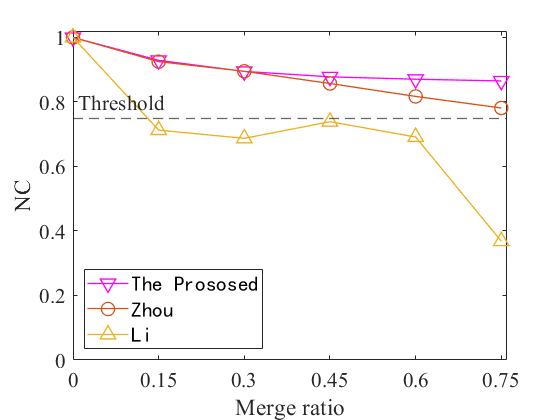

clear;
FONT_SIZE=16;
YLineWidth=1;
pLineWidth=1;
pMarkerSize=10;
font2="SimHei";
namearr=[
    "The Prososed"
    "Zhou"
    "Li"
    
    ]';

% 删除


% xf=0.1:0.2:1.9;
xf=0:0.15:0.75;

% yf=[
%     1.00  1.00  1.00  1.00
%     1.00  1.00  1.00  1.00
%     1.00  1.00  1.00  1.00
%     1.00  1.00  0.98  1.00
%     1.00  1.00  0.94  1.00
%     1.00  1.00  0.89  0.97
%     1.00  1.00  0.83  0.89
%     0.98  0.95  0.78  0.83
%     0.88  0.83  0.72  0.77
%     0.67  0.72  0.66  0.67
%     
%     ];

%% 添加
yf=[
1	1	1
0.929040216	0.925	0.7127
0.894717925	0.8951	0.6872
0.877897735	0.8572	0.7388
0.87049146	0.8172	0.6913
0.8652	0.7813	0.3684

   ];

% %% 裁剪
% yf=[
% 1	1	1
% 0.929040216	0.925	0.7127
% 0.894717925	0.8951	0.6872
% 0.877897735	0.8572	0.7388
% 0.87049146	0.8172	0.6913
% 0.8652	0.7813	0.3684
% 
% 
%    ];


% figure;
pobj=plot(xf,yf(:,1),'vm-',...
    xf,yf(:,2),'o-',...
    xf,yf(:,3),'^-'...
    );

for i=1:3
    pobj(i).LineWidth=pLineWidth;
    pobj(i).MarkerSize=pMarkerSize;
end

font= 'Times New Roman';
fontsize=FONT_SIZE;


set(gca,'FontSize',fontsize , 'Fontname', font);

%xlabel("删除比例 \fontname{Times new roman}(%)",FontName=font2);
% 缩放
% xlabel("Scaling factor");
% ylabel('NC')
% ylim([0.6,1.02])
% xlim([0.1,2]);
% 旋转
xlabel("Merge ratio");
ylabel('NC')
ylim([0.0,1.02])
xlim([0,0.76]);

xticks(xf)

% yobject=yline(0.75,'--',"阈值","linewidth",YLineWidth);
yobject=yline(0.75,'--',"Threshold","linewidth",YLineWidth);
set(yobject,"FontName",font,"FontSize",fontsize,"LabelHorizontalAlignment",'left')
% set(yobject,"FontName",font2,"FontSize",fontsize,"LabelHorizontalAlignment",'left')
lobject=legend(namearr,'Interpreter','none', "Location", 'southwest');
set(lobject,"FontName",font2,"FontSize",fontsize)

## 图层攻击

clear;
FONT_SIZE=16;
YLineWidth=1;
pLineWidth=1;
pMarkerSize=10;
font2="SimHei";
namearr=[
        "Add Layer"
        "Remove Layer"

    ]';

% 删除


% xf=0.1:0.2:1.9;
xf=0:1:6;

% yf=[
%     1.00  1.00  1.00  1.00
%     1.00  1.00  1.00  1.00
%     1.00  1.00  1.00  1.00
%     1.00  1.00  0.98  1.00
%     1.00  1.00  0.94  1.00
%     1.00  1.00  0.89  0.97
%     1.00  1.00  0.83  0.89
%     0.98  0.95  0.78  0.83
%     0.88  0.83  0.72  0.77
%     0.67  0.72  0.66  0.67
%     
%     ];

% %% 添加
% yf=[
%     1 1 1    
%     0.9824	0.9844	0.8108
%     0.9539	0.9844	0.8029
%     0.923	0.9688	0.7811
%     0.8984	0.9219	0.7784
%     0.8887	0.8906	0.7648
%    ];

%% 裁剪
yf=[
1   1
1	1
0.9629	1
0.9434	0.9824
0.8555	0.9668
0.8438	0.9531
0.7617	0.89
   ];


% % figure;
% pobj=plot(xf,yf(:,1),'vm-',...
%     xf,yf(:,2),'o-'...
%     );

% figure;
pobj=plot(xf,yf(:,1),'^-',...
    xf,yf(:,2),'vm-'...
    );

for i=1:2
    pobj(i).LineWidth=pLineWidth;
    pobj(i).MarkerSize=pMarkerSize;
end

font= 'Times New Roman';
fontsize=FONT_SIZE;


set(gca,'FontSize',fontsize , 'Fontname', font);

%xlabel("删除比例 \fontname{Times new roman}(%)",FontName=font2);
% 缩放
% xlabel("Scaling factor");
% ylabel('NC')
% ylim([0.6,1.02])
% xlim([0.1,2]);
% 旋转
xlabel("Number of layers");
ylabel('NC');
ylim([0.0,1.02])
xlim([0,6.2]);

xticks(xf)

% yobject=yline(0.75,'--',"阈值","linewidth",YLineWidth);
yobject=yline(0.75,'--',"Threshold","linewidth",YLineWidth);
set(yobject,"FontName",font,"FontSize",fontsize,"LabelHorizontalAlignment",'left')
% set(yobject,"FontName",font2,"FontSize",fontsize,"LabelHorizontalAlignment",'left')
lobject=legend(namearr,'Interpreter','none', "Location", 'southwest');
set(lobject,"FontName",font2,"FontSize",fontsize)

## 面图层攻击

clear;
FONT_SIZE=16;
YLineWidth=1;
pLineWidth=1;
pMarkerSize=10;
font2="SimHei";
namearr=[
        
        "Remove Polygon Layer"
        "Remove Polyline Layer"
    ]';

% 删除


% xf=0.1:0.2:1.9;
xf=0:1:5;
xff = 0:1:3;

% yf=[
%     1.00  1.00  1.00  1.00
%     1.00  1.00  1.00  1.00
%     1.00  1.00  1.00  1.00
%     1.00  1.00  0.98  1.00
%     1.00  1.00  0.94  1.00
%     1.00  1.00  0.89  0.97
%     1.00  1.00  0.83  0.89
%     0.98  0.95  0.78  0.83
%     0.88  0.83  0.72  0.77
%     0.67  0.72  0.66  0.67
%     
%     ];

% %% 添加
% yf=[
%     1 1 1    
%     0.9824	0.9844	0.8108
%     0.9539	0.9844	0.8029
%     0.923	0.9688	0.7811
%     0.8984	0.9219	0.7784
%     0.8887	0.8906	0.7648
%    ];

%% 裁剪
yf=[
1         
0.9981     
0.9341    
0.666     
0.4922
0.4668

   ];
yff = [
1
1
0.9812
0.9534
];

yff =     1.0000
    1.0000
    0.9812
    0.9534


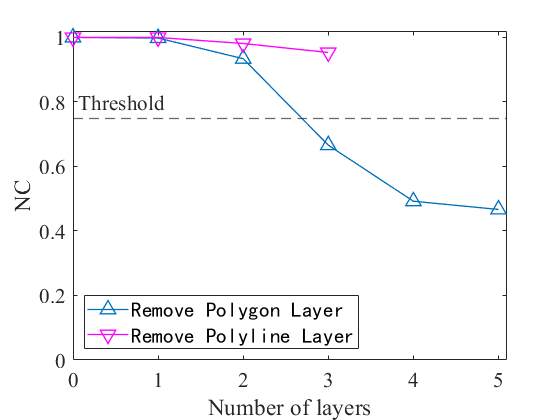



% % figure;
% pobj=plot(xf,yf(:,1),'vm-',...
%     xf,yf(:,2),'o-'...
%     );

% figure;
pobj=plot(xf,yf(:,1),'^-',...
    xff,yff(:,1),'vm-'...
    );

for i=1:2
    pobj(i).LineWidth=pLineWidth;
    pobj(i).MarkerSize=pMarkerSize;
end

font= 'Times New Roman';
fontsize=FONT_SIZE;


set(gca,'FontSize',fontsize , 'Fontname', font);

%xlabel("删除比例 \fontname{Times new roman}(%)",FontName=font2);
% 缩放
% xlabel("Scaling factor");
% ylabel('NC')
% ylim([0.6,1.02])
% xlim([0.1,2]);
% 旋转
xlabel("Number of layers");
ylabel('NC');
ylim([0.0,1.02])
xlim([0,5.1]);

xticks(xf)

% yobject=yline(0.75,'--',"阈值","linewidth",YLineWidth);
yobject=yline(0.75,'--',"Threshold","linewidth",YLineWidth);
set(yobject,"FontName",font,"FontSize",fontsize,"LabelHorizontalAlignment",'left')
% set(yobject,"FontName",font2,"FontSize",fontsize,"LabelHorizontalAlignment",'left')
lobject=legend(namearr,'Interpreter','none', "Location", 'southwest');
set(lobject,"FontName",font2,"FontSize",fontsize)